Analyse K: Max global=0.0802 (k=19). Seuil acceptation=0.0642


   > Arrêt précoce à k=9 (Score=0.0683). Gain futur négligeable (-0.0003)


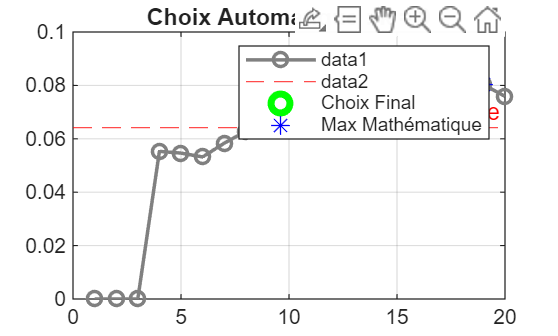

% --- DÉBUT SÉLECTION INTELLIGENTE (HYBRIDE) ---

% Données (Exemple : remplacez par vos variables)
s_values = best_SClOK; 

k_start_idx = find(s_values > 0, 1, 'first');
if isempty(k_start_idx), k_start_idx = 3; end
y_curve = s_values(k_start_idx:end);
x_curve = k_start_idx : length(s_values);

% --- ÉTAPE 1 : Chercher un VRAI PIC (Priorité 1) ---
% 'MinPeakProminence' : Il faut que le pic descende d'au moins 0.002 après
[pks, locs] = findpeaks(y_curve, 'MinPeakProminence', 0.003); 

if ~isempty(locs)
    % SI UN PIC EST TROUVÉ : On prend le premier pic significatif
    % (C'est la logique de parcimonie : on préfère k=9 à k=25)
    best_idx = locs(1); 
    NClini = x_curve(best_idx);
    method_used = 'Pic Détecté (Peak)';
    
else
    % --- ÉTAPE 2 : Méthode GÉOMÉTRIQUE (Priorité 2) ---
    % Si aucun pic net n'est trouvé (courbe plate ou montée lente),
    % on utilise la méthode du "Point le plus loin de la diagonale".
    
    % Normalisation [0, 1] pour que x et y aient le même poids
    y_norm = (y_curve - min(y_curve)) / (max(y_curve) - min(y_curve));
    x_norm = (x_curve - min(x_curve)) / (max(x_curve) - min(x_curve));
    
    % La diagonale virtuelle (y = x dans l'espace normalisé)
    % Distance verticale à la diagonale : (y - x)
    distances = y_norm - x_norm;
    
    % On cherche le point qui maximise cette distance (le coude)
    [~, best_idx] = max(distances);
    NClini = x_curve(best_idx);
    method_used = 'Coude Géométrique (Elbow)';
end

% fprintf('>>> Résultat BestK : k = %d (Score: %.4f)\n', NClini, s_values(NClini));
% fprintf('>>> Méthode utilisée : %s\n', method_used);

% --- VISUALISATION ---
fig = figure(Visible="off");
plot(x_curve, y_curve, '-o', 'LineWidth', 1.5, 'Color', [0.2 0.2 0.2]); hold on;
plot(NClini, s_values(NClini), 'rx', 'MarkerSize', 12, 'LineWidth', 3);
title(['Choix Final : k=' num2str(NClini) ' (' method_used ')']);
grid on;
xlabel('Nombre de clusters'); ylabel('Silhouette');
namegraph = fullfile(namefull, 'selectionK.png');
if isfolder(namefull)
    exportgraphics(fig, namegraph, 'Resolution', 150);
    close(fig);
end
